Import data table and convert to array

load datatable.mat
data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961
    0.0010    0.1200    0.3000    0.0035    0.1180    1.4769
    0.0010    0.1200    0.3000    0.0050    0.1180    1.7975
    0.0010    0.1200    0.4000    0.0020    0.1204    0.8060
    0.0010    0.1200    0.4000    0.0035    0.1204    1.4875
    0.0010    0.1200    0.4000    0.0050    0.1205    1.8221
    0.0010    0.1200    0.5000    0.0020    0.1221    0.8606
    0.0010    0.1200    0.5000    0.0035    0.1221    1.4049
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9555
    0.0010    0.1400    0.3000    0.0020    0.1398    0.8128


p = data(:,1:4)';
t = data(:,5:6)';

p1 = p(1,:);
p2 = p(2,:);
p3 = p(3,:);
p4 = p(4,:);

t1 = t(1,:);
t2 = t(2,:);

p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));

pn = [p1n p2n p3n p4n]';
tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
%net0.inputs{1}.processFcns   = {'removeconstantrows'};
%net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,p,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    14



disp('Which has MSE =')

Which has MSE =


disp(M0)

   9.1776e-04



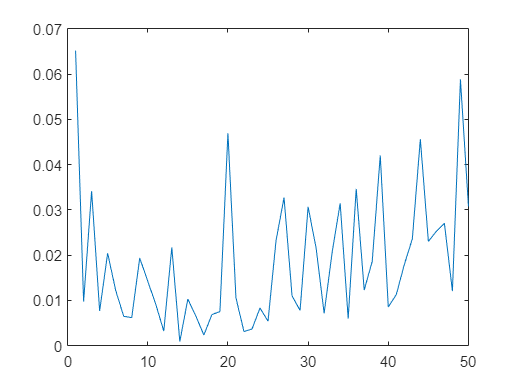

hold off;

net1 = fitnet(14,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 14
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
%net1.inputs{1}.processFcns   = {'removeconstantrows'};
%net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'poslin';

[net1,tr1] = train(net1,p,tn);

output_ANN1 = net1(p)

output_ANN1 =     0.5082    0.5020    0.5108    0.5367    0.5227    0.5220    0.5257    0.5170    0.5320    0.7171    0.7193    0.7256    0.6856    0.6895    0.6922    0.7569    0.7408    0.7354    0.9345    0.9378    0.9409    0.9108    0.9012    0.9153    0.9679    0.9518    0.9504    0.9829    0.9620    0.9406    0.1923    0.2005    0.1764    0.2122    0.1977    0.1971    0.3110    0.3145    0.3001    0.3013    0.3111    0.2957    0.3339    0.3284    0.3402    0.4489    0.4557    0.4272    0.4309    0.4410
    0.0687    0.5358    0.6827    0.1170    0.4713    0.7406    0.0987    0.4464    0.8540    0.0537    0.6271    0.6400    0.0985    0.4987    0.7057    0.1608    0.4474    0.7981   -0.0094    0.6415    0.5365    0.0286    0.4792    0.5877    0.1405    0.4271    0.6349    0.0671    0.6359    0.5926    0.0880    0.6247    0.6631    0.1375    0.5377    0.7815    0.0537    0.6771    0.5455    0.0799    0.6115    0.6140    0.1596    0.5126    0.6960    0.0473    0.7716    0.4663    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   118.3948  117.7477  118.6629  121.3723  119.9042  119.8342  120.2259  119.3146  120.8833  140.2475  140.4725  141.1357  136.9516  137.3565  137.6446  144.4065  142.7205  142.1575  162.9876  163.3334  163.6562  160.5059  159.5004  160.9836  166.4793  164.7932  164.6485  168.0456  165.8619  163.6225   85.3408   86.2048   83.6835   87.4314   85.9074   85.8441   97.7598   98.1316   96.6199   96.7432   97.7740   96.1629  100.1547   99.5790  100.8156  112.1857  112.9008  109.9133  110.3090  111.3608


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    0.8318    1.5265    1.7451    0.9036    1.4307    1.8312    0.8764    1.3936    1.9998    0.8094    1.6623    1.6815    0.8760    1.4714    1.7793    0.9688    1.3951    1.9167    0.7156    1.6837    1.5276    0.7722    1.4423    1.6038    0.9386    1.3649    1.6739    0.8293    1.6754    1.6111    0.8605    1.6588    1.7159    0.9342    1.5293    1.8921    0.8095    1.7367    1.5410    0.8484    1.6391    1.6428    0.9670    1.4921    1.7649    0.7999    1.8772    1.4232    0.8370    1.7185


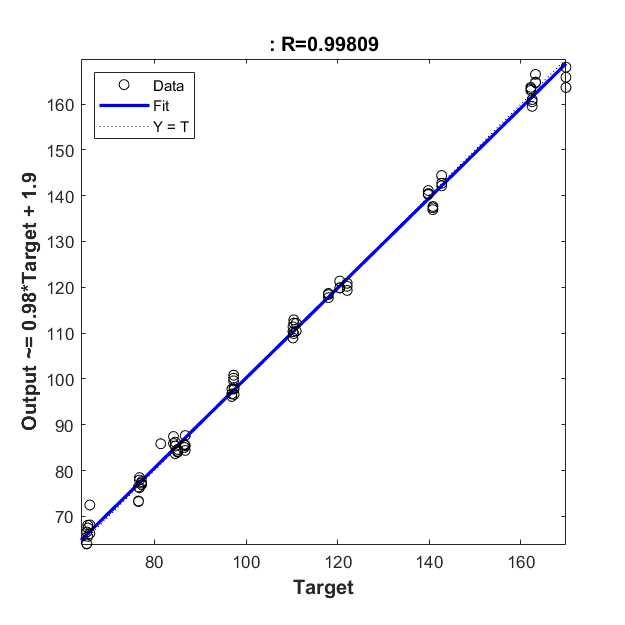

plotregression(t1,ANNIPF)

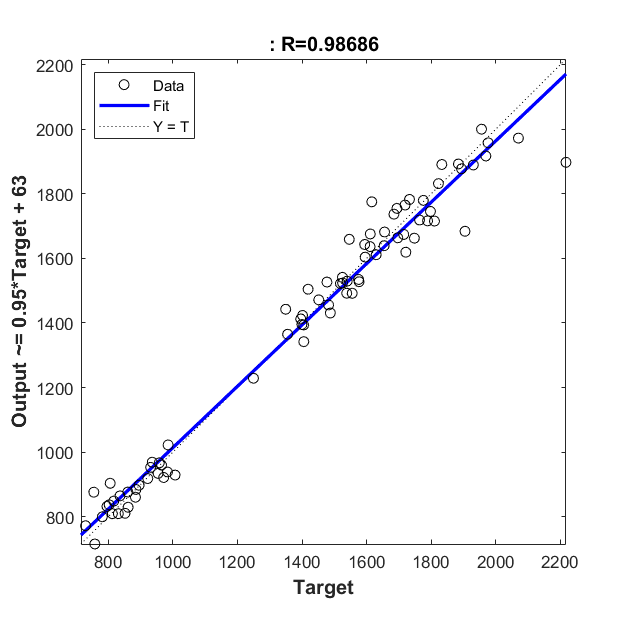

plotregression(t2,ANNSEA)

%plotregression(t1,output_ANN1(1,:));
%plotregression(t2,output_ANN1(2,:));

pred = net1([0.75 0.75 0.75 0.75]')

pred =     0.7033
    0.4865



IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 138.7970

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

SEA = 1.4532e+03